clear all
close all
D = 15; %15ps/nm/km
delta_lambda = 0.1; %nm
tau_0 = 0.5; %ns
L = [10 50 100]; %km

$D
$ is a dispersion coefficient in units of ns / (km.nm)

$\Delta\lambda$is the optical linewidth

$\tau_{0} $ is the width of Gaussian pulse

$L$is the length of the fibre

delta_tau = D*delta_lambda*L/1000; %ns


$$\Delta\tau = D\Delta\lambda L$$


tau = (tau_0^2 + delta_tau.^2).^0.5;

$\Delta \tau$ is the dispersion induced pulse broadening such that the total pulse width is $ \tau^{2} = \tau _{0}^{2}+\Delta\tau^{2}$

P_0 = 1;
t = -2:0.01:2; % ns
P_t_10 = P_0/tau(1) * exp(-t.^2/2/tau(1)^2);
P_t_50 = P_0/tau(2) * exp(-t.^2/2/tau(2)^2);
P_t_100 = P_0/tau(3) * exp(-t.^2/2/tau(3)^2);


$$P(t) = P_{0}exp(-\frac{t^{2}}{2\tau_{0}^{2}})$$


$P_{0}$ is the input power (peak), $t
$ is time

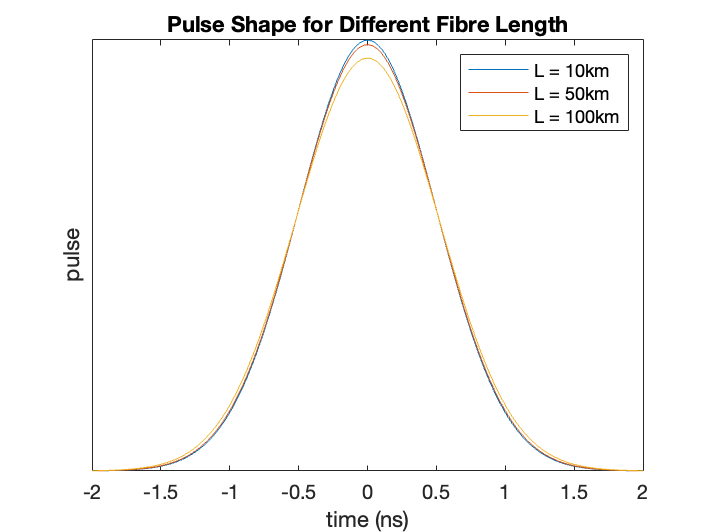

figure(1);
plot(t,P_t_10)
hold on
plot(t,P_t_50)
plot(t,P_t_100)
title('Pulse Shape for Different Fibre Length')
xlabel('time (ns)') 
ylabel('pulse') 
set(gca,'YTick', [])
legend({'L = 10km','L = 50km','L = 100km'},'Location','northeast')

(a)

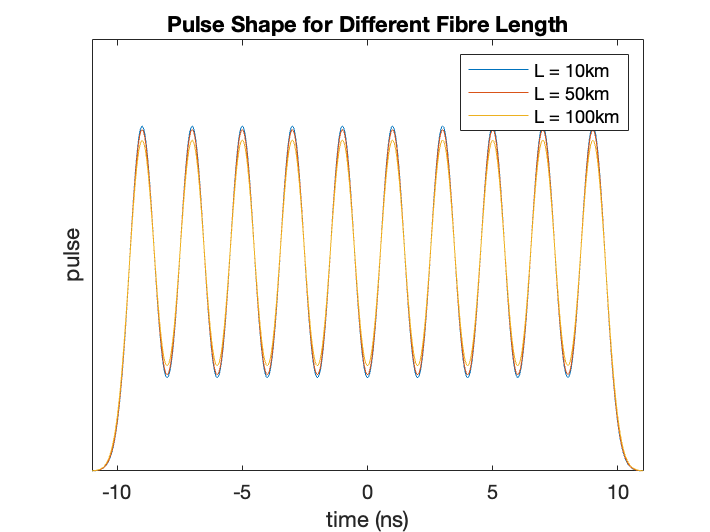

interval_a = 2; % ns
tau_0 = 0.5; % ns
tau = (tau_0^2 + delta_tau.^2).^0.5;

range_a = interval_a*10 + 2; %ns
resolution_a = 0.01;
P_a_10 = zeros(1,range_a/resolution_a+1);
P_a_50 = zeros(1,range_a/resolution_a+1);
P_a_100 = zeros(1,range_a/resolution_a+1);
t_a = -range_a/2:resolution_a:range_a/2;
for i = 1:10
P_temp = P_0/tau(1) * exp(-(t_a+range_a/2-i*interval_a).^2/2/tau(1)^2);
P_a_10 = P_temp + P_a_10;
P_temp = P_0/tau(2) * exp(-(t_a+range_a/2-i*interval_a).^2/2/tau(2)^2);
P_a_50 = P_temp + P_a_50;
P_temp = P_0/tau(3) * exp(-(t_a+range_a/2-i*interval_a).^2/2/tau(3)^2);
P_a_100 = P_temp + P_a_100;
end
figure(2)
plot(t_a,P_a_10)
hold on 
plot(t_a,P_a_50)
plot(t_a,P_a_100)
xlim([-11 11])
title('Pulse Shape for Different Fibre Length')
xlabel('time (ns)') 
ylabel('pulse') 
set(gca,'YTick', [])
legend({'L = 10km','L = 50km','L = 100km'},'Location','northeast')

(b)

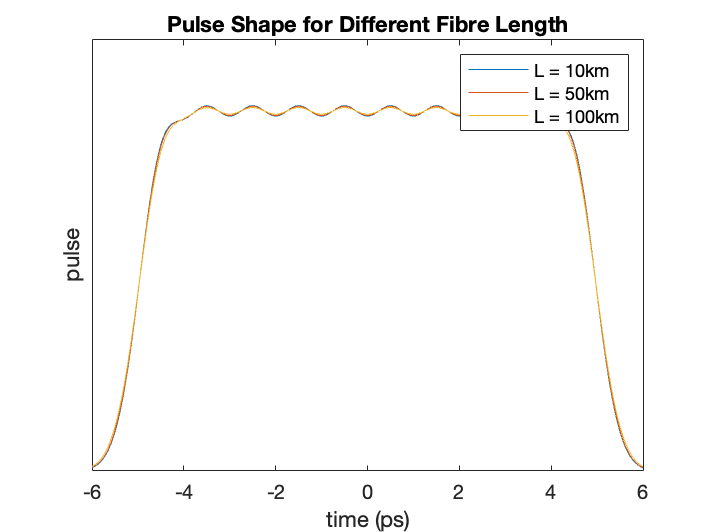

interval_b = 1; % ns
tau_0 = 0.5; % ns
tau = (tau_0^2 + delta_tau.^2).^0.5;

range_b = 10*interval_b + 2; %ns
resolution_b = 0.01;
P_b_10 = zeros(1,range_b/resolution_b+1);
P_b_50 = zeros(1,range_b/resolution_b+1);
P_b_100 = zeros(1,range_b/resolution_b+1);
t_b = -range_b/2:resolution_b:range_b/2;
for i = 1:10
P_temp = P_0/tau(1) * exp(-(t_b+(range_b-1)/2-i*interval_b).^2/2/tau(1)^2);
P_b_10 = P_temp + P_b_10;
P_temp = P_0/tau(2) * exp(-(t_b+(range_b-1)/2-i*interval_b).^2/2/tau(2)^2);
P_b_50 = P_temp + P_b_50;
P_temp = P_0/tau(3) * exp(-(t_b+(range_b-1)/2-i*interval_b).^2/2/tau(3)^2);
P_b_100 = P_temp + P_b_100;
end
figure(3)
plot(t_b,P_b_10)
hold on 
plot(t_b,P_b_50)
plot(t_b,P_b_100)
xlim([-6 6])
title('Pulse Shape for Different Fibre Length')
xlabel('time (ps)') 
ylabel('pulse') 
set(gca,'YTick', [])
legend({'L = 10km','L = 50km','L = 100km'},'Location','northeast')

(c)

interval_c = 2; % ns
tau_0 = 0.5; % ns
tau = (tau_0^2 + delta_tau.^2).^0.5;

range_c = 15 * interval_c + 2; %ns
resolution_c = 0.01;
P_c_10 = zeros(1,range_c/resolution_c+1);
P_c_50 = zeros(1,range_c/resolution_c+1);
P_c_100 = zeros(1,range_c/resolution_c+1);
t_c = -range_c/2:resolution_c:range_c/2;
random_pulse = [1 1 0 0 1 0 1 0 1 0 0 0 1 1 0];
%random_pulse = round(rand(1,15));
t_pulse = -14:2:14;
for i = 1:15
    if random_pulse(i)==1
        P_temp = P_0/tau(1) * exp(-(t_c+range_c/2-i*interval_c).^2/2/tau(1)^2);
        P_c_10 = P_temp + P_c_10;
        P_temp = P_0/tau(2) * exp(-(t_c+range_c/2-i*interval_c).^2/2/tau(2)^2);
        P_c_50 = P_temp + P_c_50;
        P_temp = P_0/tau(3) * exp(-(t_c+range_c/2-i*interval_c).^2/2/tau(3)^2);
        P_c_100 = P_temp + P_c_100;
    end
end
str = ['The random sequence of pulses is ',num2str(random_pulse),'.'];
disp(str);

The random sequence of pulses is 1  1  0  0  1  0  1  0  1  0  0  0  1  1  0.


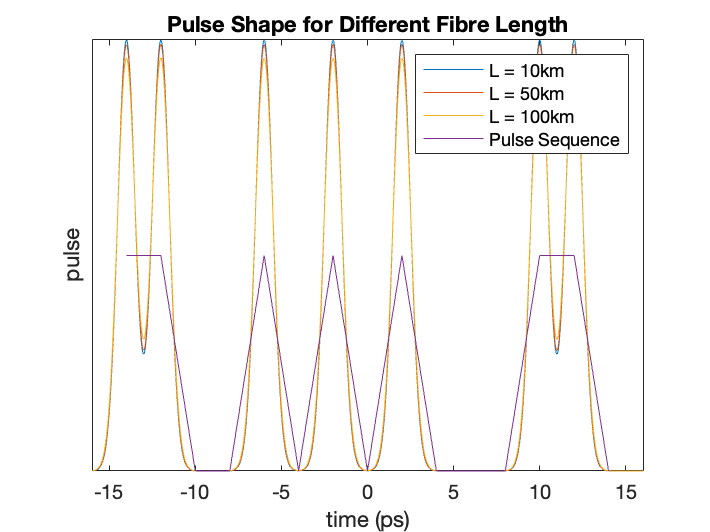

figure(4)
plot(t_c,P_c_10)
hold on 
plot(t_c,P_c_50)
plot(t_c,P_c_100)
plot(t_pulse,random_pulse)
xlim([-16 16])
ylim([0 2])
title('Pulse Shape for Different Fibre Length')
xlabel('time (ps)') 
ylabel('pulse') 
set(gca,'YTick', [])
legend({'L = 10km','L = 50km','L = 100km','Pulse Sequence'},'Location','northeast')